# Compute Yield to Maturity for Bonds with Stepped Coupons

Find the yield to maturity of three stepped-coupon bonds of known price, given three conversion scenarios:

- Bond A has two conversions, the first one falling on the settle date and immediately expiring.

- Bond B has three conversions, with conversion dates exactly on the coupon dates.

- Bond C has three conversions, with one or more conversion dates not on coupon dates. This case illustrates that only cash flows for full periods after conversion dates are affected, as illustrated below.

The following table illustrates the interest-rate characteristics of this bond portfolio.

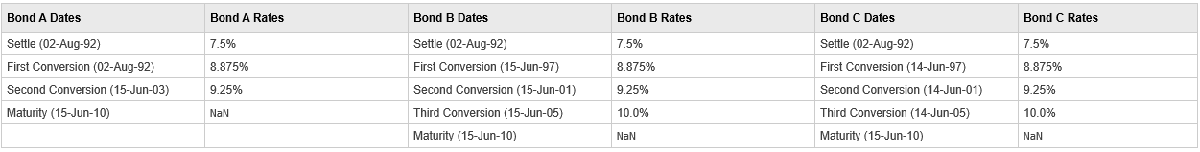

Define the specifications for the bonds.

format long
Price = [117.3824; 113.4339; 113.4339];
Settle = datenum('02-Aug-1992');

ConvDates = [datenum('02-Aug-1992'), datenum('15-Jun-2003'), nan;
datenum('15-Jun-1997'), datenum('15-Jun-2001'), datenum('15-Jun-2005'); 
datenum('14-Jun-1997'), datenum('14-Jun-2001'), datenum('14-Jun-2005')];
        
Maturity = datenum('15-Jun-2010');

CouponRates = [0.075 0.08875 0.0925 nan;
               0.075 0.08875 0.0925 0.1;
               0.075 0.08875 0.0925 0.1];
Basis = 1;
Period = 2;
EndMonthRule = 1;
Face = 100;

Use [stepcpnyield](docid:fininst_ug.btxewww-2315) to compute the yield to maturity for the bonds with stepped coupons.

Yield = stepcpnyield(Price, Settle, Maturity, ConvDates, CouponRates, Period, Basis, EndMonthRule, Face)

*Copyright 2020 The MathWorks, Inc.*